# Digital Signal Processing -- Homework 5

#### Moving Average and Windowed SINC Filters

# Problem 1 -- Moving Average Filters (20 Points)

In MATLAB create an impulse response for a moving average filter with a kernel of length.  Plot the frequency response of the filter using the freqz function.  Apply the filter to the data in the MATLAB data file XX.mat.  Now create an impulse response of a MAV filter that is XX in filter length.  Plot the frequency response of the filter.  Apply this filter to the data from the MATLAB file

 Create an impulse response for a Moving average filter of length 31.  Recall that the impulse response for a Moving average filter is a kernal

 with all the same values where the value is one over the length of the  filter.

 For example    hMAV = [1/N, 1/N, 1/N, 1/N,...... 1/N];  where N is the

 length of the filter.

 Hint:  One easy way to create a vector of all the same values in MATLAB  is to use the "ones(N,M)" function.  This creates a matrix of size N by

 M of all ones.  You can use "ones(1,N) to create a row vector of all  ones.  Then you can scale the vector by the magnitude of the value that

 you want for all the elements.  That is if I want a vector of length 20 where all the values are 3 I would use

 x = ones(1,20) * 3;

Here is an example of creating a length 11 moving average filter in MATLAB

## MAV Filter Example

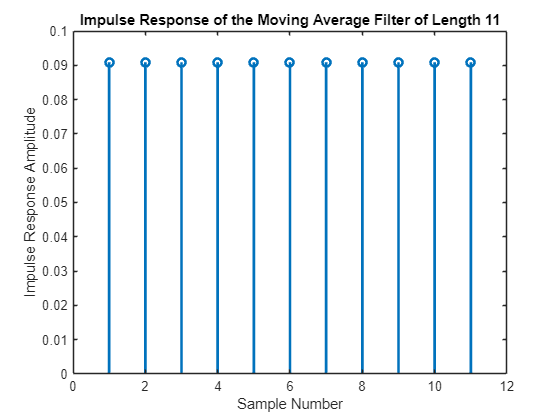

% Example

filterLength = 11;
hMAV11 = ones(1,filterLength) * (1/filterLength);

%  Plot the impulse response. Use the STEM function to plot the individual
%  values of the response

figure
stem( hMAV11, 'LineWidth',2 )
title('Impulse Response of the Moving Average Filter of Length 11');
xlabel('Sample Number');
ylabel('Impulse Response Amplitude')

## Plot the Frequency Response of a Digital Filter

Plot the frequency response of the filter.  Use the freqz function.

The freqz function is in the form of:

[h,w] = freqz( b, a, numFreqSamples )

where b is the numerator and a is  the denominator of the z-transform of the filter.  In the case of an  FIR filter, the denominator a is just 1 and numerator is the impulse

response of the filter hMAV.  


$$H(z) = \frac{h[0] + h[1]z^{-1}+h[2]z^{-2}+...+h[N-1]z^{n-1}}{1}
$$


The number of samples is the number of  samples in the frequency domain.  The output value h is a vector of the complex

value of the frequency response.  The vector w is a vector of the frequency points corresponding to the points in the frequency response.  The

frequency values represent the points around the circle in the z-domain from angle 0 to pi.

See <help freqz> in MATLAB for more (and better) information

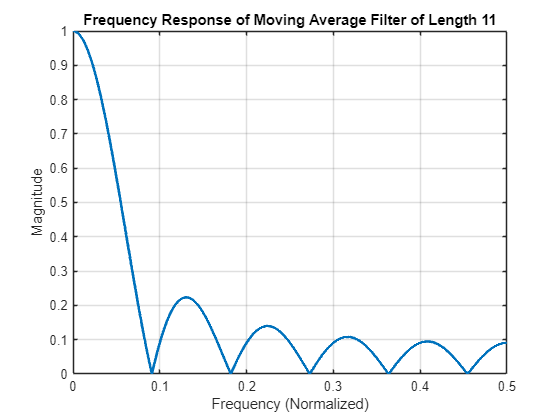

%  Compute the frequency response of the filter

nSamples = 2048;
[h,w] = freqz(hMAV11, 1, nSamples);

figure
plot(w/(2*pi), abs(h),'LineWidth',2 );
grid on
title('Frequency Response of Moving Average Filter of Length 11')
xlabel('Frequency (Normalized)');
ylabel('Magnitude')

## Create a length 31 Moving Average Filter (10 pts)

Now create your own impulse response of the moving average filter for a length of 31.  Be sure to create a new variable name for the impulse response to keep it separate from the length 11 MAV impulse response.  You'll use both again.  Plot the impulse response and the frequency response of the filter.

Use appropriate titles and axes labels

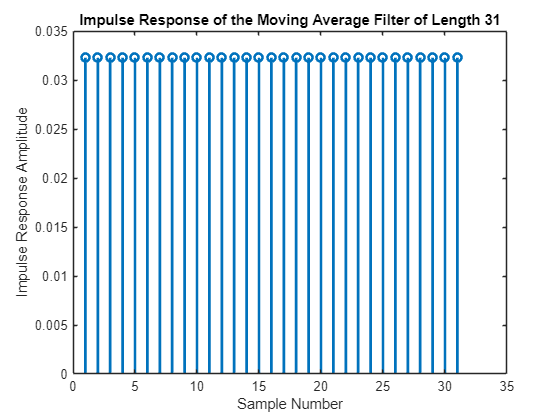

%  Your solution goes here
filterLength31 = 31;

hMAV31 = ones(1, filterLength31) * (1/filterLength31);


%  Compute the frequency response.  Be sure to create a new variable for
%  the frequency respone and the frequency vector as you'll use these
%  again.
figure;
stem(hMAV31, 'LineWidth', 2);
title('Impulse Response of the Moving Average Filter of Length 31');
xlabel('Sample Number');
ylabel('Impulse Response Amplitude');

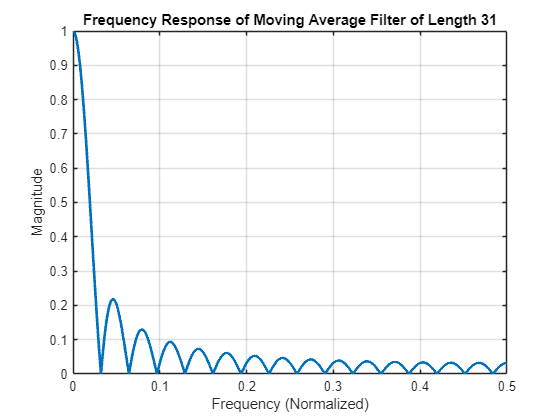


nSamples = 2048;      % number of points for freqz
[h31, w31] = freqz(hMAV31, 1, nSamples);

figure;
plot(w31/(2*pi), abs(h31), 'LineWidth', 2);
grid on;
title('Frequency Response of Moving Average Filter of Length 31');
xlabel('Frequency (Normalized)');
ylabel('Magnitude');

## Create a length 101 Moving Average Filter (10 pts)

Now create a Moving Average filter with impulse response of length 101. Be sure to name it differently than the filter of length 31 as you will use them both again. Compute the frequency response of the filter.  Again use a new variable name for both the frequency response and the frequency.  Plot the frequency response of both the length 31 and length 101 moving average filters.

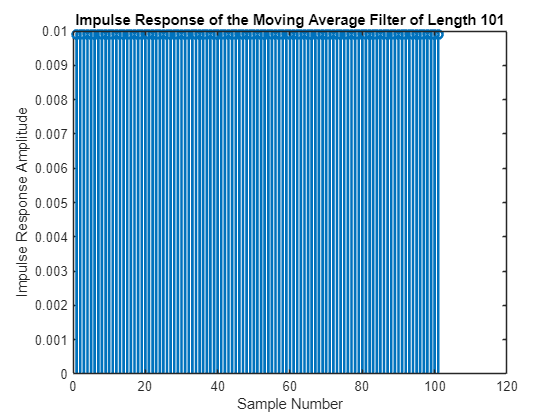

%   Moving Average filter of length 101.  Plot both frequency responses on
%   the same graph

%  Your solution goes here

filterLength101 = 101;

hMAV101 = ones(1, filterLength101) * (1/filterLength101);

%  Compute and plot the frequency response
figure;
stem(hMAV101, 'LineWidth', 2);
title('Impulse Response of the Moving Average Filter of Length 101');
xlabel('Sample Number');
ylabel('Impulse Response Amplitude');

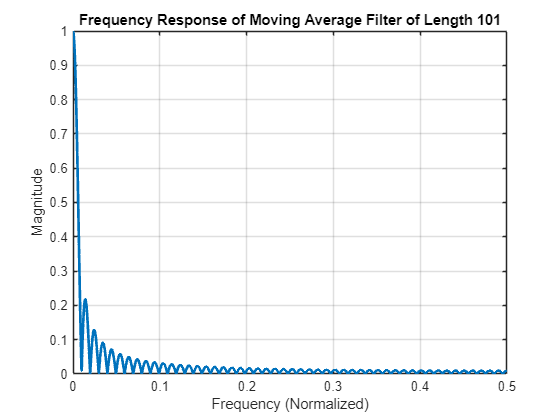


nSamples = 2048;      % number of points for freqz
[h101, w101] = freqz(hMAV101, 1, nSamples);

figure;
plot(w101/(2*pi), abs(h101), 'LineWidth', 2);
grid on;
title('Frequency Response of Moving Average Filter of Length 101');
xlabel('Frequency (Normalized)');
ylabel('Magnitude');

# Problem 2 -- Apply the MAV filter to an input signal (20 pts)

The moving average filter is an FIR filter.  We will implement the filter using convolution.  MATLAB has a function to perform convolution. 

It is "w = conv( u, v )".  Use the MATLAB help function to better learn how to use the convolution function.

The input arguments u and v are  the input sequences to the function.  Since convolution is commutative you can put them in either order.

The output is the variable w.  The variable w includes the end effects, so you will want to remove the end effects of the result.

Load the input signal file "HW_05_Problem_2_Signal.mat".  Convolve the input sequence from the file with the impulse response of each of the three impulse responses.  Plot the individual responses then plot all three moving average filter and plot the outputs on the same graph.  Comment on the difference between the three filters below.

1. Load the input file and plot the input variable "signal" vs "sample" (3 pts)

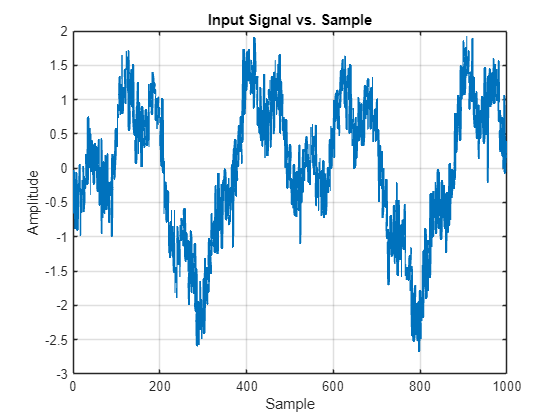

% Load the file "HW_05_Problem_2_Signal.mat".  This will load two variables into the workspace.
% One "sample" is the sample number.
% The other is "signal" and is the signal of interest.
% 

load("HW_05_Problem_2_Signal.mat");

%  load the file "HW_05_Problem_2_Signal.mat" into the workspace and plot
%  the variable signal vs the variable sample
figure;
plot(sample, signal, 'LineWidth', 2);
title('Input Signal vs. Sample');
xlabel('Sample');
ylabel('Amplitude');
grid on;

2. Convolve the input signal with the length 11 MAV filter.  Remove end effects.  Plot the output. (3 pts) 

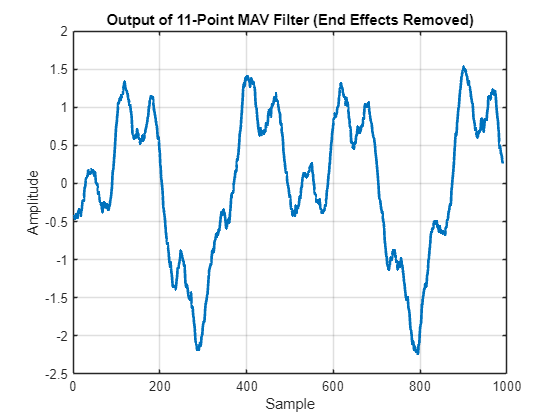


%  Convolve the input signal with the length 11 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 10 samples on the beginning and at the end

%  Place your solution here
M11 = length(hMAV11);
convOut11 = conv(signal, hMAV11); 

convOut11_noEnds = convOut11(M11:end - (M11 - 1));

figure;
plot(convOut11_noEnds, 'LineWidth', 2);
title('Output of 11-Point MAV Filter (End Effects Removed)');
xlabel('Sample');
ylabel('Amplitude');
grid on;

3. Convolve the input signal with the length 3` MAV filter.  Remove end effects.  Plot the output.(3 pts)

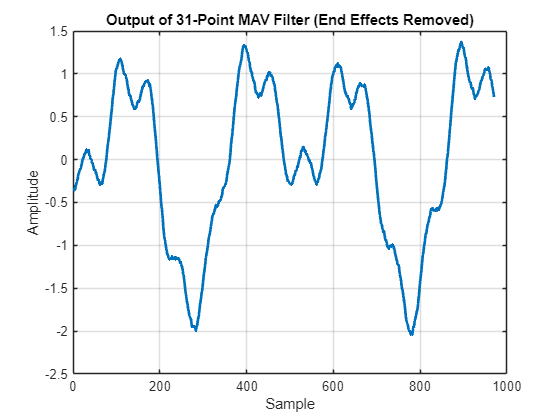


%  Convolve the input signal with the length 31 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 30 samples on the beginning and at the end

%  Place your solution here
M31 = length(hMAV31);
convOut31 = conv(signal, hMAV31); 

convOut31_noEnds = convOut31(M31:end - (M31 - 1));

figure;
plot(convOut31_noEnds, 'LineWidth', 2);
title('Output of 31-Point MAV Filter (End Effects Removed)');
xlabel('Sample');
ylabel('Amplitude');
grid on;

4. Convolve the input signal with the length 101 MAV filter.  Remove end effects.  Plot the output. (3 pts)

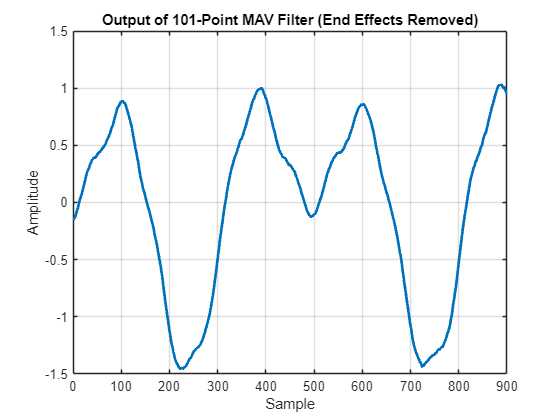

%  Convolve the input signal with the length 101 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 100 samples on the beginning and at the end

%  Place your solution here
M101 = length(hMAV101);
convOut101 = conv(signal, hMAV101); 

convOut101_noEnds = convOut101(M101:end - (M101 - 1));

figure;
plot(convOut101_noEnds, 'LineWidth', 2);
title('Output of 101-Point MAV Filter (End Effects Removed)');
xlabel('Sample');
ylabel('Amplitude');
grid on;

5.  Plot all the convolution results on the same graph (3 pts)

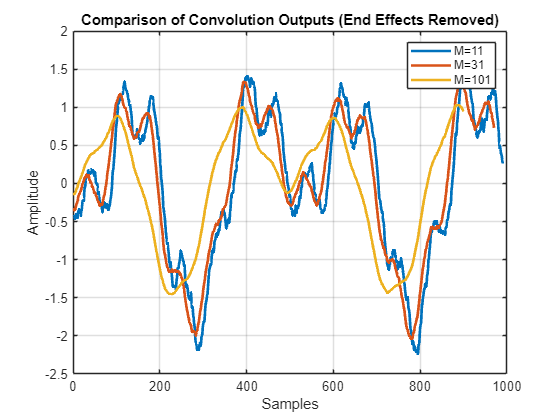

%  Plot all three convolution outputs with end effect removed on the same
%  graph below
figure;
plot(convOut11_noEnds, 'LineWidth', 2); hold on;
plot(convOut31_noEnds, 'LineWidth', 2);
plot(convOut101_noEnds, 'LineWidth', 2);
grid on;
xlabel('Samples');
ylabel('Amplitude');
title('Comparison of Convolution Outputs (End Effects Removed)');
legend('M=11','M=31','M=101');

## Questions (5 pts)

#### Which filter removed the noise the best without distorting the output.  Did any of the filters distort the output?  Why?

The M = 101 was the best at removing noise. All the filters distorted the output but the M = 101 filter caused the greatest distortion because the longer filter has more low-frequency emphasis.

# Problem 3 -- Windowed SINC Low Pass Filter (20 pts)

A)  I've done this first part for you as an example.  Using the FIR_Designer tool, I created a  truncated SINC lowpass filter with no window ('Window' parameter set to 'none') with a cut off frequency of 70 BPM assuming a sampling rate of 600 BPM.  I used a filter kernel length of 201. I plotted the impulse and the  frequency responses of the filter in decibels.. 

## Plot the impulse response -- Example

freqCornerLPF = 70;
filterLength = 201;
hLPF_trunc = FIR_Designer('nOrder', filterLength, 'cutBPM', freqCornerLPF, 'Window', 'none', 'PrintHeader', false, 'PlotResponses', false);

h = [-0.002753, -0.000992, 0.001319, 0.002993, 0.003149, 0.001673, -0.000703, -0.002765, -0.003436, -0.002337, -0.000000, 0.002390, 0.003592, 0.002956,...
0.000768, -0.001870, -0.003599, -0.003498, -0.001577, 0.001213, 0.003441, 0.003935, 0.002395, -0.000431, -0.003108, -0.004238, -0.003192, -0.000455,...
0.002595, 0.004379, 0.003932, 0.001423, -0.001901, -0.004334, -0.004580, -0.002445, 0.001033, 0.004081, 0.005098, 0.003486, -0.000000, -0.003605,...
-0.005450, -0.004511, -0.001180, 0.002889, 0.005598, 0.005478, 0.002486, -0.001926, -0.005505, -0.006345, -0.003892, 0.000707, 0.005135, 0.007063,...
0.005368, 0.000773, -0.004448, -0.007583, -0.006881, -0.002518, 0.003402, 0.007847, 0.008397, 0.004540, -0.001944, -0.007792, -0.009878, -0.006860,...
0.000000, 0.007334, 0.011289, 0.009523, 0.002542, -0.006357, -0.012595, -0.012624, -0.005876, 0.004677, 0.013763, 0.016363, 0.010379, -0.001954,...
-0.014762, -0.021189, -0.016871, -0.002556, 0.015568, 0.028263, 0.027525, 0.010913, -0.016159, 

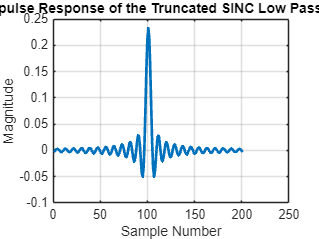

%  Plot the impulse response.
figure;
plot(hLPF_trunc,'LineWidth',2);
grid on;
title('Impulse Response of the Truncated SINC Low Pass Filter');
xlabel('Sample Number');
ylabel('Magnitude');

## Plot the frequency response -- Example

Plot the decibal magnitude of the response versus the frequency in breaths per minute.  Use 20*log10( abs( fResponseTruncatedSINC) ).  The frequency response output is complex so find the magnitude using abs().  Plot in decibels using 20*log10( x ) where x is the magnitude of the frequency response.

The freqz function creates a vector of frequencies from 0 to pi (the Nyquist frequency).  Convert that to a vector of frequencies from 0 to 300 BPM.  300 BPM is the Nyquist frequency when sampling at 600 bpm.  Do this by dividing the frequency vector by $2\pi$ then multiplying by 600 bpm the sample rate.

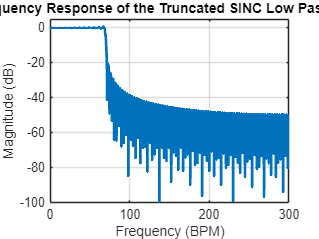

%  Plot the frequency response using the freqz function.
nSamples = 2048;  %  Use 2048 samples in the frequency response
[fResponseTruncatedSINC, wTruncatedSINC ] = freqz( hLPF_trunc, 1,  nSamples );
figure
plot(wTruncatedSINC/(2*pi)*600, 20*log10(abs(fResponseTruncatedSINC)),'LineWidth',2);
grid on
title('Frequency Response of the Truncated SINC Low Pass Filter')
xlabel('Frequency (BPM)')
ylabel('Magnitude (dB)')
xlim([0,300])
ylim([-100,5])

## Questions (5 pts)

#### What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How much attenuation is achieved in the stop band of the filter?

The pass band looks mostly flat but it does have some ripples. From the plot, attenuation reaches approximantely -80 to -90 dB in the highest frequencies.

B)  Now, your turn.  Create the same filter using a Hamming window and compare the frequency responses.  Modify the parameters of the FIR_Designer command appropriately.

## Create a Windowed SINC filter using a Hamming Window ( 10 pts)

Use the FIR_Designer function and use a Hamming window by changing the 'Window' parameter from 'none' to the value 'Hamming'.  

Plot the impulse response and the frequency response as in the example.  Create a separate variable for the Hamming window impulse response results as well as the frequency response results.


%  Create a windowed SINC low pass filter using a Hamming window

%  Put your solution here
freqCornerLPF = 70;
filterLength = 201;

hLPF_hamming = FIR_Designer('nOrder', filterLength, 'cutBPM', freqCornerLPF, 'Window', 'Hamming', 'PrintHeader', false, 'PlotResponses', false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 4096;

h = [-1, 0, 0, 1, 1, 1, 0, -1, -1, -1, 0, 1, 2, 1,...
0, -1, -2, -2, -1, 1, 2, 3, 2, 0, -3, -4, -3, 0,...
3, 5, 4, 2, -2, -5, -6, -3, 1, 6, 8, 5, 0, -6,...
-10, -8, -2, 6, 11, 11, 5, -4, -12, -14, -9, 2, 13, 18,...
14, 2, -12, -21, -19, -7, 10, 23, 25, 14, -6, -25, -32, -22,...
0, 25, 39, 33, 9, -23, -45, -46, -22, 17, 51, 62, 40, -8,...
-57, -83, -66, -10, 62, 113, 110, 44, -65, -168, -205, -130, 68, 351,...
648, 872, 956, 872, 648, 351, 68, -130, -205, -168, -65, 44, 110, 113,...
62, -10, -66, -83, -57, -8, 40, 62, 51, 17, -22, -46, -45, -23,...
9, 33, 39, 25, 0, -22, -32, -25, -6, 14, 25, 23, 10, -7,...
-19, -21, -12, 2, 14, 18, 13, 2, -9, -14, -12, -4, 5, 11,...
11, 6, -2, -8, -10, -6, 0, 5, 8, 6, 1, -3, -6, -5,...
-2, 2, 4, 5, 3, 0, -3, -4, -3, 0, 2, 3, 2, 1,...
-1, -2, -2, -1, 0, 1, 2, 1, 0, -1, -1, -1, 0, 1,...
1, 1, 0, 0, -1];


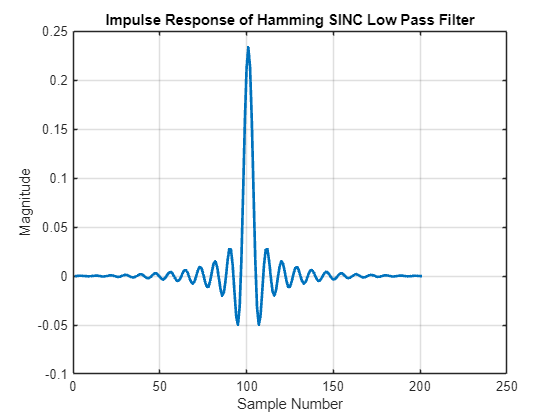

figure;
plot(hLPF_hamming, 'LineWidth', 2);
grid on;
title('Impulse Response of Hamming SINC Low Pass Filter');
xlabel('Sample Number');
ylabel('Magnitude');

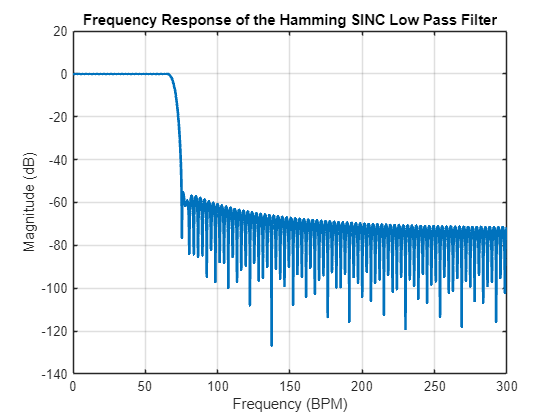

nSamples = 2048;
[fResponseHammingSINC, wHammingSINC] = freqz(hLPF_hamming, 1, nSamples);
figure;
plot(wHammingSINC/(2*pi)*600, 20*log10(abs(fResponseHammingSINC)), 'LineWidth', 2);
grid on;
title('Frequency Response of the Hamming SINC Low Pass Filter');
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');

## Questions (5 pts)

**What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How does it compare to the truncated SINC filter?  How much attenuation is achieved in the stop band of the filter?  How does it compare to the truncated SINC filter?**

The pass band is similar to the truncated but is perfectly flat. From the plot, attenuation reaches roughly -100 to -120 dB. The hamming shows better overall attenuation and smoother transition but the cutoff is slightly broader.

# Problem 4 -- Windowed SINC High Pass Filter (20 pts)

A)  Using the FIR_Designer tool, now create a truncated SINC **highpass** filter ('Window' value of 'none') with a cut off frequency of 40 BPM assuming a sampling rate of 600 BPM.  Use a filter length of 201.  Plot the impulse response and the frequency response of the filter in decibels..

B)  Then create the same filter using a Hamming window ('Window' value of 'hamming') and compare the frequency responses.

Note:  You can supress the output of the C-header code by the FIR_Designer function by adding a parameter in Name/Value pair format 'PrintHeader','false'.  You can also suppress the plotting of graphs using 'PlotResponses', false.

## Truncated SINC High Pass Filter (10 pts)

%  Place your solution here
freqCornerHPF  = 40;
filterLengthHPF= 201

filterLengthHPF = 201


hHPF_trunc = FIR_Designer( ...
    'nOrder',      filterLengthHPF, ...
    'cutBPM',      freqCornerHPF, ...
    'window',      'none', ... 
    'Type',        'HPF', ...
    'PrintHeader', false, ...
    'PlotResponses', false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 2048;

h = [6, 4, 1, -1, -4, -6, -7, -7, -5, -3, 0, 3, 5, 7,...
8, 7, 5, 2, -2, -5, -7, -8, -8, -6, -3, 0, 4, 7,...
9, 9, 8, 6, 2, -2, -6, -9, -10, -10, -8, -4, 0, 4,...
8, 11, 12, 10, 7, 3, -3, -7, -11, -13, -13, -10, -6, 0,...
6, 11, 15, 16, 14, 10, 4, -4, -11, -16, -19, -19, -15, -9,...
0, 9, 17, 23, 25, 22, 16, 6, -6, -18, -28, -34, -34, -28,...
-16, 0, 19, 37, 51, 59, 56, 42, 17, -19, -64, -112, -161, -206,...
-241, -264, 1776, -264, -241, -206, -161, -112, -64, -19, 17, 42, 56, 59,...
51, 37, 19, 0, -16, -28, -34, -34, -28, -18, -6, 6, 16, 22,...
25, 23, 17, 9, 0, -9, -15, -19, -19, -16, -11, -4, 4, 10,...
14, 16, 15, 11, 6, 0, -6, -10, -13, -13, -11, -7, -3, 3,...
7, 10, 12, 11, 8, 4, 0, -4, -8, -10, -10, -9, -6, -2,...
2, 6, 8, 9, 9, 7, 4, 0, -3, -6, -8, -8, -7, -5,...
-2, 2, 5, 7, 8, 7, 5, 3, 0, -3, -5, -7, -7, -6,...
-4, -1, 1, 4, 6];


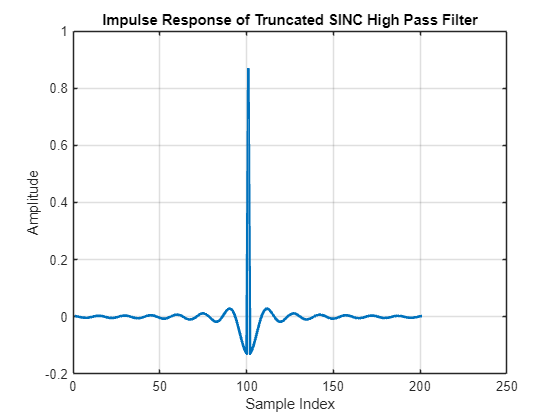

%  Plot the impulse response
figure;
plot(hHPF_trunc, 'LineWidth', 2);
grid on;
title('Impulse Response of Truncated SINC High Pass Filter');
xlabel('Sample Index');
ylabel('Amplitude');

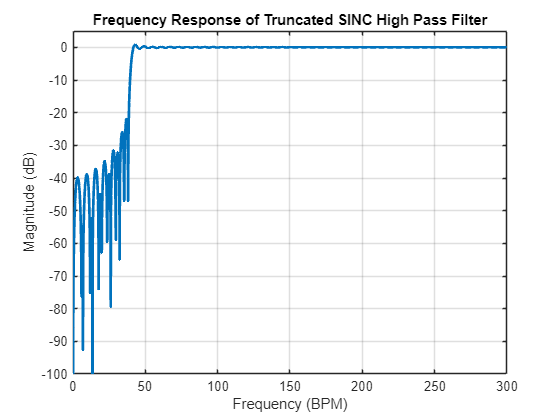

%  Plot the frequency response of the truncated SINC HPF use the
%  freqz function
nSamples = 2048;
[fResponseTruncHPF, wTruncHPF] = freqz(hHPF_trunc, 1, nSamples);
figure;
plot(wTruncHPF/(2*pi)*600, 20*log10(abs(fResponseTruncHPF)), 'LineWidth',2);
grid on;
title('Frequency Response of Truncated SINC High Pass Filter');
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
xlim([0,300]);
ylim([-100,5]);

## Questions

#### What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How much attenuation is achieved in the stop band of the filter? 

The pass band looks mostly flat but it does have some ripples. From the plot, attenuation is around -80 to -90 dB with noticable ripple lobes close to the cutoff at 40 BPM.

## Hamming Windowed SINC High Pass Filter (10 pts)

%  Place your solution here
freqCornerHPF  = 40;     % cutoff frequency in BPM
filterLengthHPF= 201;    % length of the filter kernel

hHPF_hamming = FIR_Designer( ...
    'nOrder',      filterLengthHPF, ...
    'cutBPM',      freqCornerHPF, ...
    'window',      'Hamming', ... 
    'Type',        'HPF', ...
    'PrintHeader', false, ...
    'PlotResponses', false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 4096;

h = [1, 1, 0, 0, -1, -1, -1, -1, -1, -1, 0, 1, 1, 2,...
2, 2, 1, 0, -1, -2, -2, -3, -3, -2, -1, 0, 2, 3,...
4, 5, 4, 3, 1, -1, -4, -6, -7, -7, -6, -3, 0, 4,...
7, 10, 11, 10, 7, 3, -3, -8, -12, -15, -15, -12, -7, 0,...
8, 14, 19, 21, 19, 14, 5, -5, -16, -24, -29, -29, -24, -14,...
0, 15, 29, 39, 43, 39, 28, 10, -11, -33, -51, -63, -64, -53,...
-31, 0, 36, 72, 100, 115, 110, 84, 33, -38, -127, -224, -323, -412,...
-484, -530, 3550, -530, -484, -412, -323, -224, -127, -38, 33, 84, 110, 115,...
100, 72, 36, 0, -31, -53, -64, -63, -51, -33, -11, 10, 28, 39,...
43, 39, 29, 15, 0, -14, -24, -29, -29, -24, -16, -5, 5, 14,...
19, 21, 19, 14, 8, 0, -7, -12, -15, -15, -12, -8, -3, 3,...
7, 10, 11, 10, 7, 4, 0, -3, -6, -7, -7, -6, -4, -1,...
1, 3, 4, 5, 4, 3, 2, 0, -1, -2, -3, -3, -2, -2,...
-1, 0, 1, 2, 2, 2, 1, 1, 0, -1, -1, -1, -1, -1,...
-1, 0, 0, 1, 1];


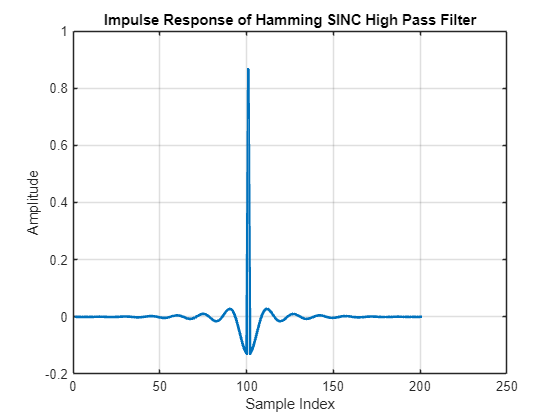

%  Plot the impulse response
figure;
plot(hHPF_hamming, 'LineWidth', 2);
grid on;
title('Impulse Response of Hamming SINC High Pass Filter');
xlabel('Sample Index');
ylabel('Amplitude');

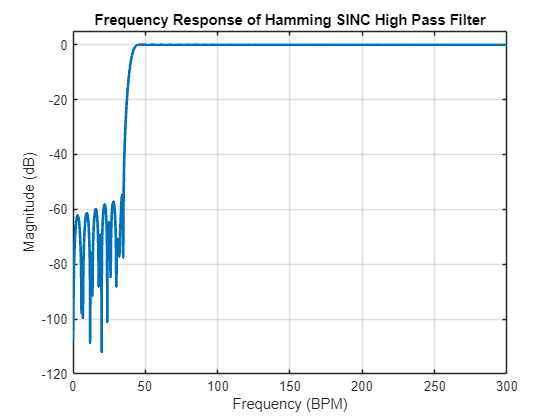

%  Plot the frequency response of the truncated SINC HPF use the
%  freqz function
nSamples = 2048;
[fResponseHammingHPF, wHammingHPF] = freqz(hHPF_hamming, 1, nSamples);
figure;
plot(wHammingHPF/(2*pi)*600, 20*log10(abs(fResponseHammingHPF)), 'LineWidth',2);
grid on;
title('Frequency Response of Hamming SINC High Pass Filter');
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
xlim([0,300]);
ylim([-120,5]);

## Questions

#### What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How does it compare to the truncated SINC filter?  How much attenuation is achieved in the stop band of the filter?  How does it compare to the truncated SINC filter?

The pass band is similar to the truncated but is perfectly flat. From the plot, attenuation is about -100 dB. The hamming shows better overall attenuation and smoother transition but the cutoff is slightly broader during the transition region.

# Problem 5 Creating a BandPass Filter  (20 pts)

Combine the Hamming Windowed SINC LPF and the Hamming Windowed SINC HPF impulse responses in a way that they will create a bandpass filter.  Refer to Chapter 14 of Smith and lectures from week 8.  

By placing the lowpass and the highpass filters in series what do you know about the resulting impulse response of the cascaded systems.  How would you calculate the resulting impulse response?

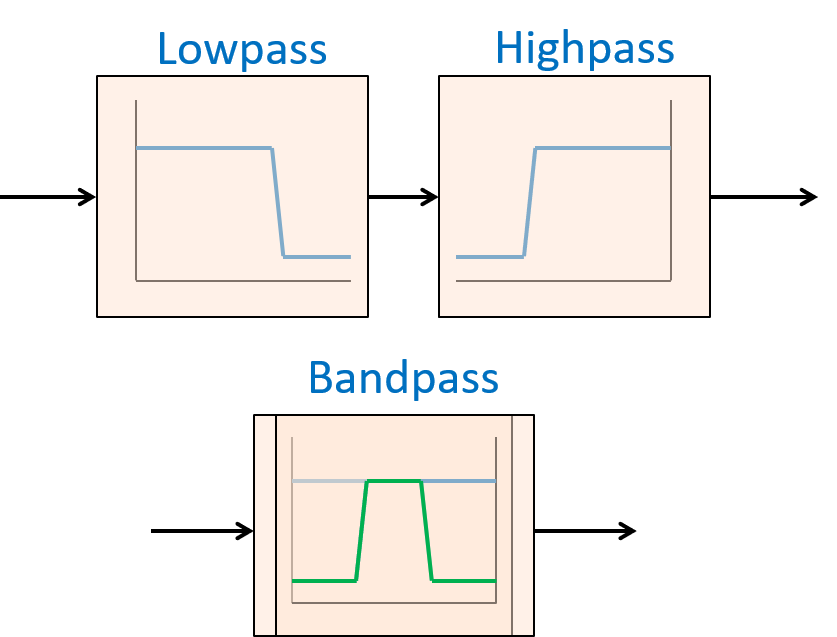

## Bandpass Filter Creation

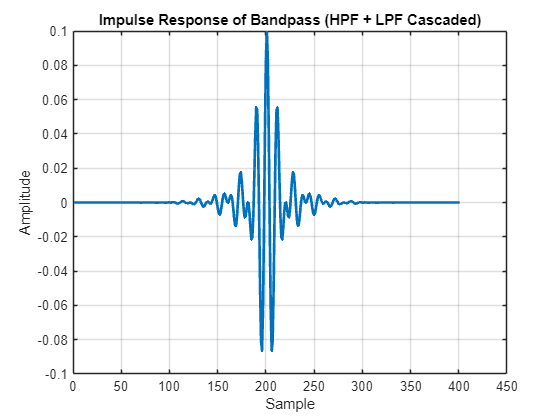

%  Create the impulse response of a bandpass filter from the lowpass and
%  high pass filter impulse responses.
%
%  Place your solution here
hBandpass = conv(hLPF_hamming, hHPF_hamming);
%  Plot the impulse response and the frequency response of the bandpass
%  filter
figure
plot(hBandpass, 'LineWidth',2)
grid on
title('Impulse Response of Bandpass (HPF + LPF Cascaded)')
xlabel('Sample')
ylabel('Amplitude')

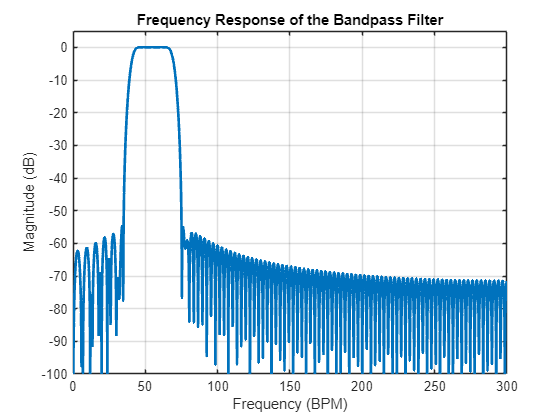

%  Plot the frequency response
[fResponseBandpass, wBandpass] = freqz(hBandpass, 1, nSamples);
figure
plot(wBandpass/(2*pi)*600, 20*log10(abs(fResponseBandpass)), 'LineWidth',2)
grid on
title('Frequency Response of the Bandpass Filter')
xlabel('Frequency (BPM)')
ylabel('Magnitude (dB)')
xlim([0,300])
ylim([-100,5])